## Minimum Time

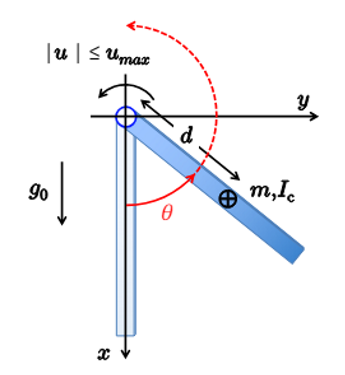

### Dynamic model

syms q1 dq1 d m I positive

x = d*cos(q1);
y = d*sin(q1);

vx = diff(x,q1)*dq1;
vy = diff(y,q1)*dq1;

T_tr = 0.5*m1*[vx vy]*[vx; vy;];
T_rot = 0.5*I*dq1^2;

T = T_rot+T_tr;

% Inertia Matrix
M11 = diff(diff(T, dq1), dq1);

M = [M11;];

M = simplify(M);

disp('The inertia matrix M(q) is:');

The inertia matrix M(q) is:


disp(M);

$$m_{1}\,d^{2}+\text{I}$$


% Potential Energy and Gravity Terms
U1 = m1*g0*(d*cos(q1));
U = [U1;];
g_q = simplify([diff(U,q1);], Steps=100)

$$g\_q = -d\,g_{0}\,m_{1}\,\sin\left(q_{1}\right)$$


% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(1,1));

% using the Christoffel symbols for a 3-DOF system
q  = [q1;];
dq = [dq1;];

% Inizializza la matrice C(q, dq) (3x3) a zeri simbolici:
C = sym(zeros(1,1));

% Formula dei coefficienti di Christoffel (Robotics):
%   C(i,j) = 1/2 * SUM_k [ dM(i,j)/dq_k + dM(i,k)/dq_j - dM(k,j)/dq_i ] * dq_k
% Poi il vettore c(q,dq) = C(q,dq) * dq
for i = 1:1
    for j = 1:1
        % Costruisco ogni elemento C(i,j):
        tmp = 0;
        for k = 1:1
            tmp = tmp + 0.5 * ( ...
                diff(M(i,j), q(k)) + ...
                diff(M(i,k), q(j)) - ...
                diff(M(k,j), q(i)) ) * dq(k);
        end
        C(i,j) = simplify(tmp);  % semplifico
    end
end

% Finalmente calcolo il vettore c(q, dq):
c_vec = simplify(C * dq);

disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$0$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$0$$


disp('La matrice di Coriolis C(q,dq) è:');

La matrice di Coriolis C(q,dq) è:


disp(C);

$$0$$


disp('Il vettore c(q,dq) = C(q,dq)*dq è:');

Il vettore c(q,dq) = C(q,dq)*dq è:


disp(c_vec);

$$0$$